syms s
R1 =100

R1 = 100

R2 = 10

R2 = 10

L = 25e-6

L = 2.5000e-05

C1 = 6.8e-6

C1 = 6.8000e-06

C2 = 150e-6

C2 = 1.5000e-04

Zout=1/(1/R1+s*C1+s*C2/(s*R2*C2+1)+1/(s*L))

$$Zout = \frac{1}{\frac{8028023020878397\,s}{1180591620717411303424}+\frac{3\,s}{20000\,\left(\frac{3\,s}{2000}+1\right)}+\frac{40000}{s}+\frac{1}{100}}$$

Z=R1*s*L*(s*R2*C2+1)/(s^3*R2*C2*R1*C1*L+s^2*(L*R2*C2+R1*L*C1+R1*C2*L)+s*(R1*R2*C2+L)+R1)

$$Z = \frac{s\,\left(\frac{3\,s}{2000}+1\right)}{400\,\left(\frac{24084069062635191\,s^{3}}{944473296573929042739200000}+\frac{8113025617570051\,s^{2}}{18889465931478580854784}+\frac{6001\,s}{40000}+100\right)}$$

a=subs(Zout,s,100)

$$a = \frac{169710045478127874867200}{67888044303825701498779467}$$

b=subs(Z,s,100)

$$b = \frac{33942009095625574973440}{13577608860765140299788231}$$

simplifyFraction(Z)

$$ans = \frac{1180591620717411303424\,s\,\left(3\,s+2000\right)}{24084069062635191\,s^{3}+405651280878502550000\,s^{2}+141694606318503704636948480\,s+94447329657392904273920000000}$$

simplifyFraction(Zout)

$$ans = \frac{29514790517935282585600\,s\,\left(3\,s+2000\right)}{602101726565879775\,s^{3}+10141282021962563103248\,s^{2}+3542365157962592615923712000\,s+2361183241434822606848000000000}$$

numerator=[R1*R2*C2 R1]

numerator =     0.1500  100.0000


denominator=[R2*C2*R1*C1*L L*R2*C2+R1*L*C1+R1*C2*L R1*R2*C2+L R1]

denominator =     0.0000    0.0000    0.1500  100.0000


SYS=tf(numerator,denominator)


SYS =
 
                 0.15 s + 100
  -------------------------------------------
  2.55e-11 s^3 + 4.295e-07 s^2 + 0.15 s + 100
 
Continuous-time transfer function.



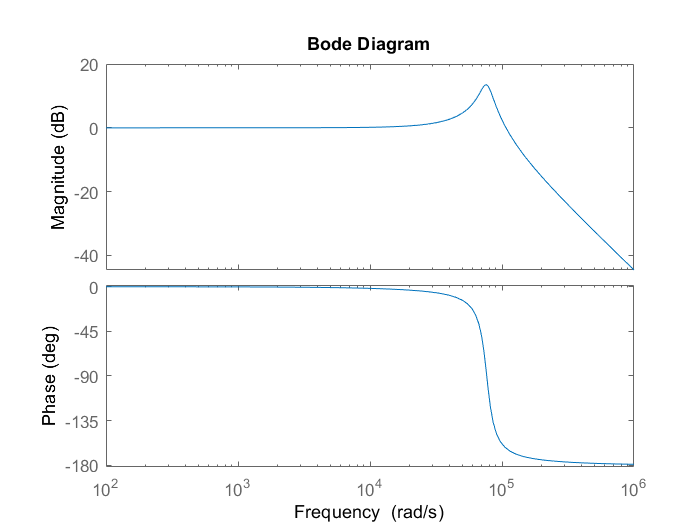

bode(SYS,{100 1e6})

a1=1/R1*(R1*R2*C2+L)

a1 = 0.0015

a2=1/R1*(L*R2*C2+R1*L*C1+R1*C2*L)

a2 = 4.2950e-09

a3=R2*C2*C1*L

a3 = 2.5500e-13

w1=1/(R2*C2)

w1 = 666.6667

w2=1/a1

w2 = 666.5556

w3=a1/a2

w3 = 3.4930e+05

w4=a2/a3

w4 = 1.6843e+04

Q=1/(sqrt(a3)*a2)

Q = 4.6107e+14

%f1=w1/(2*pi)
%f2=w2/(2*pi)
%f3=w3/(2*pi)
%f4=w4/(2*pi)
f11=1/(2*pi*R1*C1)

f11 = 234.0514

f21=1/(2*pi*R2*C1)

f21 = 2.3405e+03

f12=1/(2*pi*R1*C2)

f12 = 10.6103

f22=1/(2*pi*R2*C2)

f22 = 106.1033

f1L=R1/(2*pi*L)

f1L = 6.3662e+05

f2L=R2/(2*pi*L)

f2L = 6.3662e+04

f01=1/(2*pi*sqrt(L*C1))

f01 = 1.2207e+04

f02=1/(2*pi*sqrt(L*C2))

f02 = 2.5990e+03

sqrt(L/C1)

ans = 1.9174

Ro=L/C1

Ro = 3.6765

Q=R2/Ro

Q = 2.7200

wo=1/sqrt(L*C1)

wo = 7.6696e+04

num=[1.917]

num = 1.9170

denom=[1/wo^2 1/(Q*wo) 1]

denom =     0.0000    0.0000    1.0000


sys=tf(num,denom)


sys =
 
              1.917
  -----------------------------
  1.7e-10 s^2 + 4.794e-06 s + 1
 
Continuous-time transfer function.



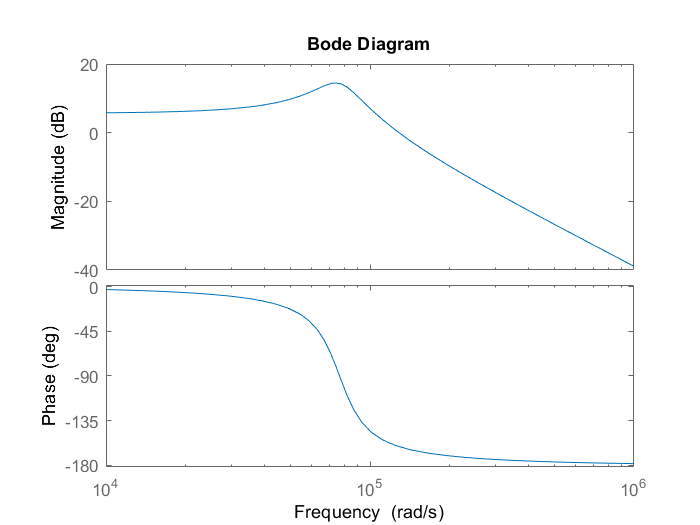

bode(sys)